# **Mechanistic Nonlinear Dynamical Modeling for Parameter Estimation: A Comparison of Physics Informed Neural Networks and Genetic Algorithms**

**Paul A. Valle¹, Yolocuauhtli Salazar², Jesus B. Páez-Lerma³, N. Oscar Soto-Cruz³, Luis N. Coria¹, Iván A. García¹, Michell V. González-Campos³**

¹ Posgrado en Ciencias de la Ingeniería, BioMath Research Group, Tecnológico Nacional de México/IT Tijuana, Tijuana, México. paul.valle@tectijuana.edu.mx, luis.coria@tectijuana.edu.mx, D25210003@tectijuana.edu.mx

²Departamento de Ingeniería Eléctrica y Electrónica, Tecnológico Nacional de México/IT Durango, Durango, México. ysalazar@itdurango.edu.mx

³Departamento de Ingenierías Química y Bioquímica, Tecnológico Nacional de México/IT Durango, Durango, México. jpaez@itdurango.edu.mx, nsoto@itdurango.edu.mx

clc; clear; close all; warning('off','all');
rho0 = [0.01;0.01;0.001;0.1;0.1;0.1;0.01;0.01];

## Raw data

### E1: 20 g/L - 125 rpm and E2: 28.78 g/L - 117 rpm

E1_raw = readmatrix("data.xlsx","Sheet","E1");
E1_w = smoothdata(E1_raw(:,2), 'gaussian', 5);
E1_x = smoothdata(E1_raw(:,3), 'gaussian', 5);
E1_y = smoothdata(E1_raw(:,4), 'gaussian', 5);
E1_z = smoothdata(E1_raw(:,5), 'gaussian', 5);
E1_t = E1_raw(:,1); E1 = [E1_w;E1_x;E1_y;E1_z];
rhoE1 = Experiment(E1_t,E1,rho0);...
E1_model = model([E1_x(1);E1_y(1);E1_z(1)],rhoE1,max(E1_t));

Degrees of freedom: 36
t-student value: 2.0281
Significance value (alpha): 0.05
 
    Parameters    Estimate        SE           MoE        ci_low      ci_high       Pvalue  
    __________    _________    _________    _________    _________    ________    __________

     {["p1"]}      0.026689     0.002231    0.0045246     0.022165    0.031214    4.2044e-14
     {["p2"]}        0.0001     0.050734      0.10289     -0.10279     0.10299       0.99844
     {["p3"]}     0.0075597     0.002184    0.0044294    0.0031302    0.011989     0.0014022
     {["p4"]}         0.326     0.065821      0.13349      0.19251     0.45949    1.7354e-05
     {["p6"]}       0.20153      0.02174     0.044091      0.15744     0.24562    4.5232e-11
     {["p8"]}           0.1 

E2_raw = readmatrix("data.xlsx","Sheet","E2");
E2_w = smoothdata(E2_raw(:,2), 'gaussian', 5);
E2_x = smoothdata(E2_raw(:,3), 'gaussian', 5); 
E2_y = smoothdata(E2_raw(:,4), 'gaussian', 5); 
E2_z = smoothdata(E2_raw(:,5), 'gaussian', 5);
E2_t = E2_raw(:,1); E2 = [E2_w;E2_x;E2_y;E2_z];
rhoE2 = Experiment(E2_t,E2,rho0);...
E2_model = model([E2_x(1);E2_y(1);E2_z(1)],rhoE2,max(E2_t));

Degrees of freedom: 36
t-student value: 2.0281
Significance value (alpha): 0.05
 
    Parameters    Estimate        SE           MoE         ci_low      ci_high       Pvalue  
    __________    _________    _________    _________    __________    ________    __________

     {["p1"]}      0.016057    0.0016295    0.0033048      0.012753    0.019362    9.1878e-12
     {["p2"]}        0.0001     0.078598       0.1594       -0.1593      0.1595       0.99899
     {["p3"]}     0.0048161    0.0029399    0.0059625    -0.0011464    0.010779        0.1101
     {["p4"]}       0.31753     0.085052      0.17249       0.14504     0.49003    0.00065119
     {["p6"]}       0.21104     0.037071     0.075183       0.13586     0.28622    1.7888e-06
     {["p8"]}        

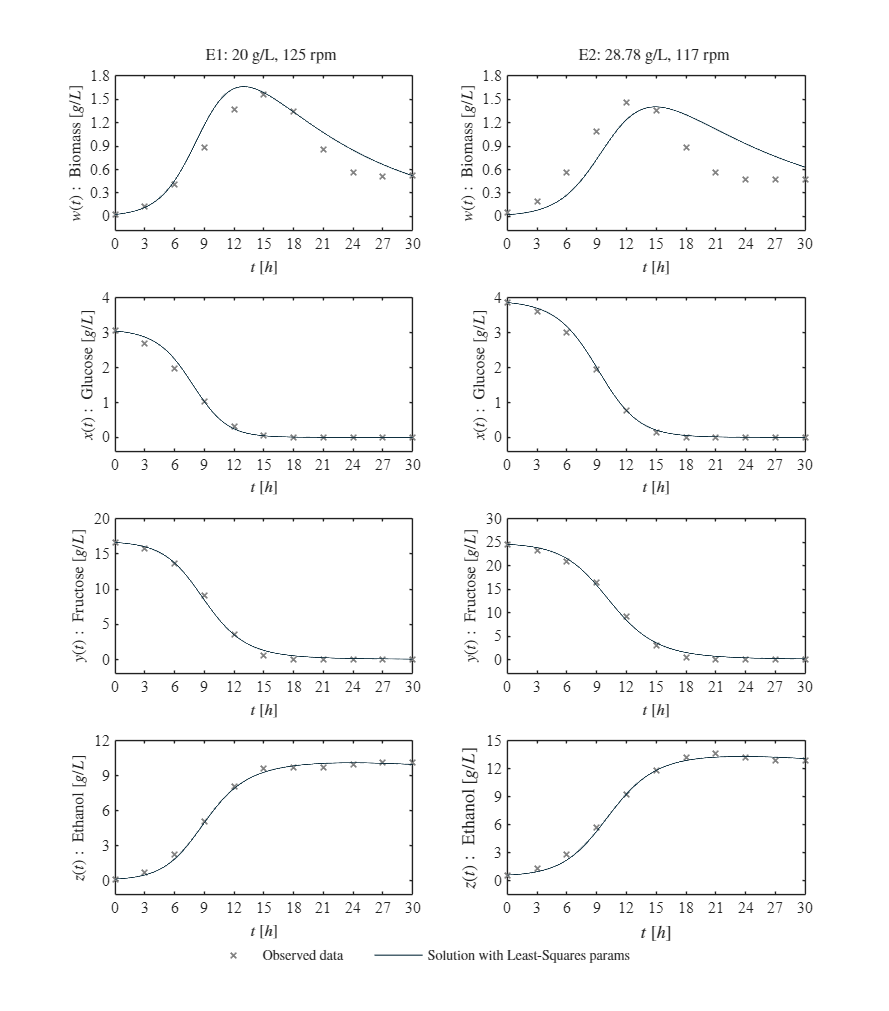

plot4x2([E1_t;E1],E1_model,[E2_t;E2],E2_model);...
subplot(4,2,1); ylim([-1.8/10 1.8]); yticks(0:0.3:1.8);...
subplot(4,2,3); ylim([-4/10 4]); yticks(0:1:4);...
subplot(4,2,5); ylim([-20/10 20]); yticks(0:5:20);...
subplot(4,2,7); ylim([-12/10 12]); yticks(0:3:12);...
subplot(4,2,2); ylim([-1.8/10 1.8]); yticks(0:0.3:1.8);...
subplot(4,2,4); ylim([-4/10 4]); yticks(0:1:4);...
subplot(4,2,6); ylim([-30/10 30]); yticks(0:5:30);...
subplot(4,2,8); ylim([-15/10 15]); yticks(0:3:15);...
dim = [0.22 0.86 0.1 0.1];...
str = {'E1: 20 g/L, 125 rpm'};...
A1 = annotation('textbox', dim, 'String', str, 'FitBoxToText', 'on','EdgeColor', 'none','FontSize',10);
set(A1,'Interpreter','Latex');...
dim = [0.64 0.86 0.1 0.1];...
str = {'E2: 28.78 g/L, 117 rpm'};...
A2 = annotation('textbox', dim, 'String', str, 'FitBoxToText', 'on','EdgeColor', 'none','FontSize',10);
set(A2,'Interpreter','Latex');...
exportgraphics(gcf,'ITD00185_E1E2.pdf','ContentType','vector')

### E3: 28.78 g/L - 142 rpm and E4: 50 g/L - 100 rpm

E3_raw = readmatrix("data.xlsx","Sheet","E3");
E3_w = smoothdata(E3_raw(:,2), 'gaussian', 5);
E3_x = smoothdata(E3_raw(:,3), 'gaussian', 5);
E3_y = smoothdata(E3_raw(:,4), 'gaussian', 5);
E3_z = smoothdata(E3_raw(:,5), 'gaussian', 5);
E3_t = E3_raw(:,1); E3 = [E3_w;E3_x;E3_y;E3_z];
rhoE3 = Experiment(E3_t,E3,rho0);...
E3_model = model([E3_x(1);E3_y(1);E3_z(1)],rhoE3,max(E3_t));

Degrees of freedom: 36
t-student value: 2.0281
Significance value (alpha): 0.05
 
    Parameters    Estimate        SE           MoE         ci_low      ci_high       Pvalue  
    __________    _________    _________    _________    __________    ________    __________

     {["p1"]}      0.017341    0.0019426    0.0039397      0.013402    0.021281    1.1769e-10
     {["p2"]}        0.0001     0.087951      0.17837      -0.17827     0.17847        0.9991
     {["p3"]}     0.0061157    0.0038373    0.0077824    -0.0016666    0.013898       0.11973
     {["p4"]}       0.27574     0.081355        0.165       0.11074     0.44073     0.0017116
     {["p6"]}       0.20374     0.038769     0.078627       0.12511     0.28236    6.8753e-06
     {["p8"]}        

E4_raw = readmatrix("data.xlsx","Sheet","E4");
E4_w = smoothdata(E4_raw(:,2), 'gaussian', 5);
E4_x = smoothdata(E4_raw(:,3), 'gaussian', 5);
E4_y = smoothdata(E4_raw(:,4), 'gaussian', 5);
E4_z = smoothdata(E4_raw(:,5), 'gaussian', 5);
E4_t = E4_raw(:,1); E4 = [E4_w;E4_x;E4_y;E4_z];
rhoE4 = Experiment(E4_t,E4,rho0);...
E4_model = model([E4_x(1);E4_y(1);E4_z(1)],rhoE4,max(E4_t));

Degrees of freedom: 36
t-student value: 2.0281
Significance value (alpha): 0.05
 
    Parameters    Estimate         SE           MoE         ci_low        ci_high       Pvalue  
    __________    _________    __________    _________    ___________    _________    __________

     {["p1"]}     0.0092183    0.00079156    0.0016054       0.007613     0.010824    9.1185e-14
     {["p2"]}        0.0001      0.062032      0.12581       -0.12571      0.12591       0.99872
     {["p3"]}     0.0014525     0.0014856    0.0030129     -0.0015604    0.0044655       0.33473
     {["p4"]}       0.31331      0.083438      0.16922        0.14409      0.48253    0.00061214
     {["p6"]}       0.19616      0.038908     0.078908        0.11725      0.27507    1.3228e-05


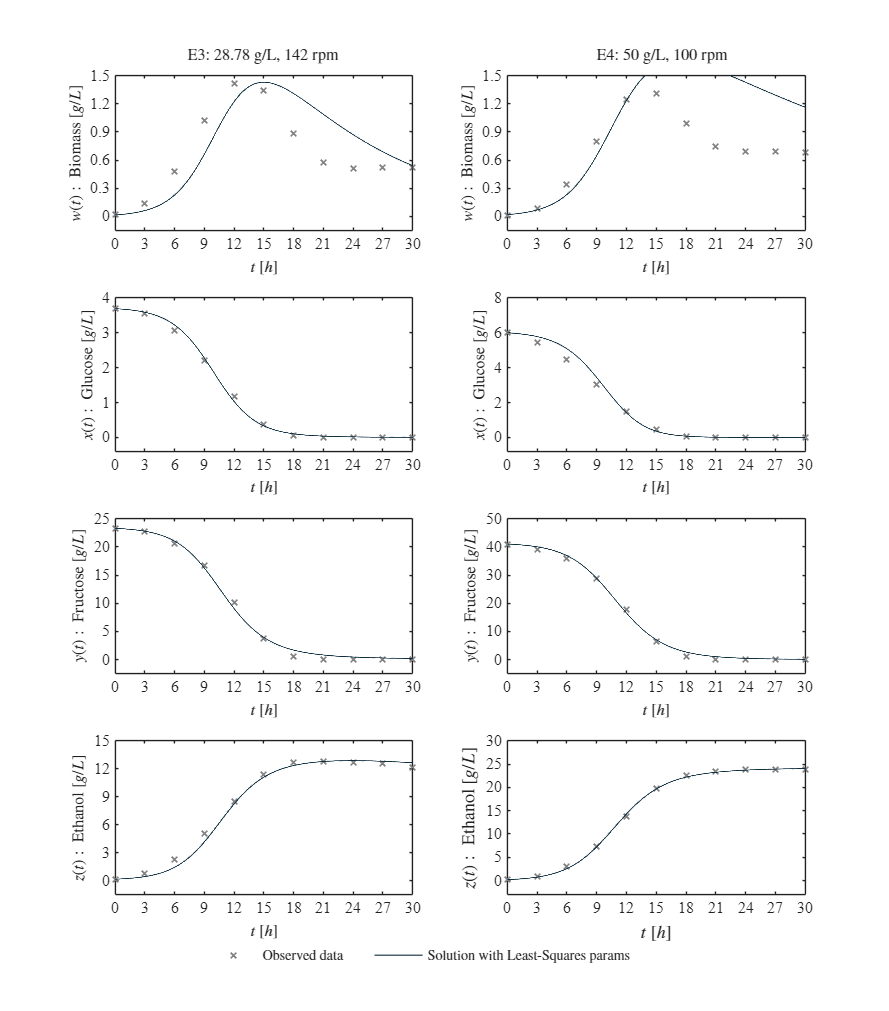

plot4x2([E3_t;E3],E3_model,[E4_t;E4],E4_model);...
subplot(4,2,1); ylim([-1.5/10 1.5]); yticks(0:0.3:1.5);...
subplot(4,2,3); ylim([-4/10 4]); yticks(0:1:4);...
subplot(4,2,5); ylim([-25/10 25]); yticks(0:5:25);...
subplot(4,2,7); ylim([-15/10 15]); yticks(0:3:15);...
subplot(4,2,2); ylim([-1.5/10 1.5]); yticks(0:0.3:1.5);...
subplot(4,2,4); ylim([-8/10 8]); yticks(0:2:8);...
subplot(4,2,6); ylim([-50/10 50]); yticks(0:10:50);...
subplot(4,2,8); ylim([-30/10 30]); yticks(0:5:30);...
dim = [0.2 0.86 0.1 0.1];...
str = {'E3: 28.78 g/L, 142 rpm'};...
A3 = annotation('textbox', dim, 'String', str, 'FitBoxToText', 'on','EdgeColor', 'none','FontSize',10);
set(A3,'Interpreter','Latex');...
dim = [0.66 0.86 0.1 0.1];...
str = {'E4: 50 g/L, 100 rpm'};...
A4 = annotation('textbox', dim, 'String', str, 'FitBoxToText', 'on','EdgeColor', 'none','FontSize',10);
set(A4,'Interpreter','Latex');...
exportgraphics(gcf,'ITD00185_E3E4.pdf','ContentType','vector')

### E5: 50 g/L - 125 rpm and E6: 50 g/L - 125 rpm

E5_raw = readmatrix("data.xlsx","Sheet","E5");
E5_w = smoothdata(E5_raw(:,2), 'gaussian', 5);
E5_x = smoothdata(E5_raw(:,3), 'gaussian', 5);
E5_y = smoothdata(E5_raw(:,4), 'gaussian', 5);
E5_z = smoothdata(E5_raw(:,5), 'gaussian', 5);
E5_t = E5_raw(:,1); E5 = [E5_w;E5_x;E5_y;E5_z];
rhoE5 = Experiment(E5_t,E5,rho0);...
E5_model = model([E5_x(1);E5_y(1);E5_z(1)],rhoE5,max(E5_t));

Degrees of freedom: 36
t-student value: 2.0281
Significance value (alpha): 0.05
 
    Parameters    Estimate         SE           MoE         ci_low       ci_high       Pvalue  
    __________    _________    __________    _________    __________    _________    __________

     {["p1"]}     0.0096934    0.00062764    0.0012729     0.0084205     0.010966    1.8559e-17
     {["p2"]}        0.0001      0.051106      0.10365      -0.10355      0.10375       0.99845
     {["p3"]}     0.0013698     0.0012853    0.0026068     -0.001237    0.0039766       0.29365
     {["p4"]}       0.25723      0.063619      0.12902       0.12821      0.38626    0.00026558
     {["p6"]}       0.21319      0.035506     0.072009       0.14118       0.2852    6.8555e-07
     {[

E6_raw = readmatrix("data.xlsx","Sheet","E6");
E6_w = smoothdata(E6_raw(:,2), 'gaussian', 5);
E6_x = smoothdata(E6_raw(:,3), 'gaussian', 5);
E6_y = smoothdata(E6_raw(:,4), 'gaussian', 5);
E6_z = smoothdata(E6_raw(:,5), 'gaussian', 5);
E6_t = E6_raw(:,1); E6 = [E6_w;E6_x;E6_y;E6_z];
rhoE6 = Experiment(E6_t,E6,rho0);...
E6_model = model([E6_x(1);E6_y(1);E6_z(1)],rhoE6,max(E6_t));

Degrees of freedom: 36
t-student value: 2.0281
Significance value (alpha): 0.05
 
    Parameters    Estimate         SE           MoE         ci_low       ci_high       Pvalue  
    __________    _________    __________    _________    __________    _________    __________

     {["p1"]}      0.010284    0.00070234    0.0014244     0.0088601     0.011709    9.7691e-17
     {["p2"]}        0.0001      0.048653     0.098673     -0.098573     0.098773       0.99837
     {["p3"]}     0.0015683     0.0012998     0.002636    -0.0010678    0.0042043       0.23546
     {["p4"]}       0.70698        0.1768      0.35856       0.34842       1.0655     0.0003025
     {["p6"]}       0.18897      0.030559     0.061977         0.127      0.25095    3.9506e-07
     {[

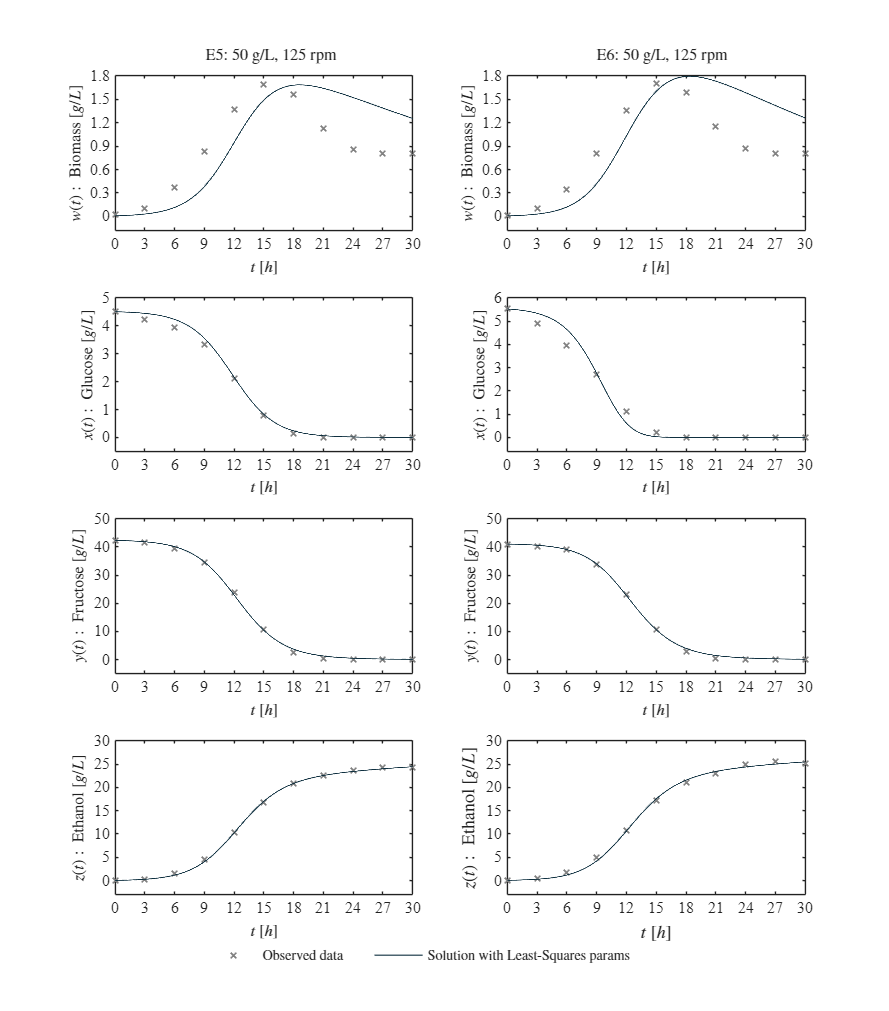

plot4x2([E5_t;E5],E5_model,[E6_t;E6],E6_model);...
subplot(4,2,1); ylim([-1.8/10 1.8]); yticks(0:0.3:1.8);...
subplot(4,2,3); ylim([-5/10 5]); yticks(0:1:5);...
subplot(4,2,5); ylim([-50/10 50]); yticks(0:10:50);...
subplot(4,2,7); ylim([-30/10 30]); yticks(0:5:30);...
subplot(4,2,2); ylim([-1.8/10 1.8]); yticks(0:0.3:1.8);...
subplot(4,2,4); ylim([-6/10 6]); yticks(0:1:6);...
subplot(4,2,6); ylim([-50/10 50]); yticks(0:10:50);...
subplot(4,2,8); ylim([-30/10 30]); yticks(0:5:30);...
dim = [0.22 0.86 0.1 0.1];...
str = {'E5: 50 g/L, 125 rpm'};...
A5 = annotation('textbox', dim, 'String', str, 'FitBoxToText', 'on','EdgeColor', 'none','FontSize',10);
set(A5,'Interpreter','Latex');...
dim = [0.66 0.86 0.1 0.1];...
str = {'E6: 50 g/L, 125 rpm'};...
A6 = annotation('textbox', dim, 'String', str, 'FitBoxToText', 'on','EdgeColor', 'none','FontSize',10);
set(A6,'Interpreter','Latex');...
exportgraphics(gcf,'ITD00185_E5E6.pdf','ContentType','vector')

### E7: 50 g/L - 150 rpm and E8: 85.36 g/L - 117 rpm

E7_raw = readmatrix("data.xlsx","Sheet","E7");
E7_w = smoothdata(E7_raw(:,2), 'gaussian', 5);
E7_x = smoothdata(E7_raw(:,3), 'gaussian', 5); 
E7_y = smoothdata(E7_raw(:,4), 'gaussian', 5);
E7_z = smoothdata(E7_raw(:,5), 'gaussian', 5);
E7_t = E7_raw(:,1); E7 = [E7_w;E7_x;E7_y;E7_z];
rhoE7 = Experiment(E7_t,E7,rho0);...
E7_model = model([E7_x(1);E7_y(1);E7_z(1)],rhoE7,max(E7_t));

Degrees of freedom: 36
t-student value: 2.0281
Significance value (alpha): 0.05
 
    Parameters    Estimate         SE           MoE         ci_low       ci_high       Pvalue  
    __________    _________    __________    _________    __________    _________    __________

     {["p1"]}     0.0095155    0.00086131    0.0017468     0.0077687     0.011262    4.0606e-13
     {["p2"]}        0.0001      0.063004      0.12778      -0.12768      0.12788       0.99874
     {["p3"]}     0.0015582     0.0015391    0.0031214    -0.0015632    0.0046796        0.3181
     {["p4"]}        0.3709        0.1027      0.20828       0.16262      0.57918    0.00092025
     {["p6"]}       0.18938      0.038129     0.077328       0.11205      0.26671    1.6627e-05
     {[

E8_raw = readmatrix("data.xlsx","Sheet","E8");
E8_w = smoothdata(E8_raw(:,2), 'gaussian', 5);
E8_x = smoothdata(E8_raw(:,3), 'gaussian', 5);
E8_y = smoothdata(E8_raw(:,4), 'gaussian', 5);
E8_z = smoothdata(E8_raw(:,5), 'gaussian', 5);
E8_t = E8_raw(:,1); E8 = [E8_w;E8_x;E8_y;E8_z];
rhoE8 = Experiment(E8_t,E8,rho0);...
E8_model = model([E8_x(1);E8_y(1);E8_z(1)],rhoE8,max(E8_t));

Degrees of freedom: 36
t-student value: 2.0281
Significance value (alpha): 0.05
 
    Parameters    Estimate         SE           MoE          ci_low       ci_high       Pvalue  
    __________    _________    __________    __________    __________    _________    __________

     {["p1"]}     0.0056908    0.00047381    0.00096094     0.0047299    0.0066518    3.7477e-14
     {["p2"]}        0.0001       0.07597       0.15407      -0.15397      0.15417       0.99896
     {["p3"]}         1e-05     0.0014644     0.0029699    -0.0029599    0.0029799       0.99459
     {["p4"]}             1       0.47338       0.96006      0.039942       1.9601      0.041649
     {["p6"]}        0.1994      0.058214       0.11806      0.081336      0.31746     0.0015496


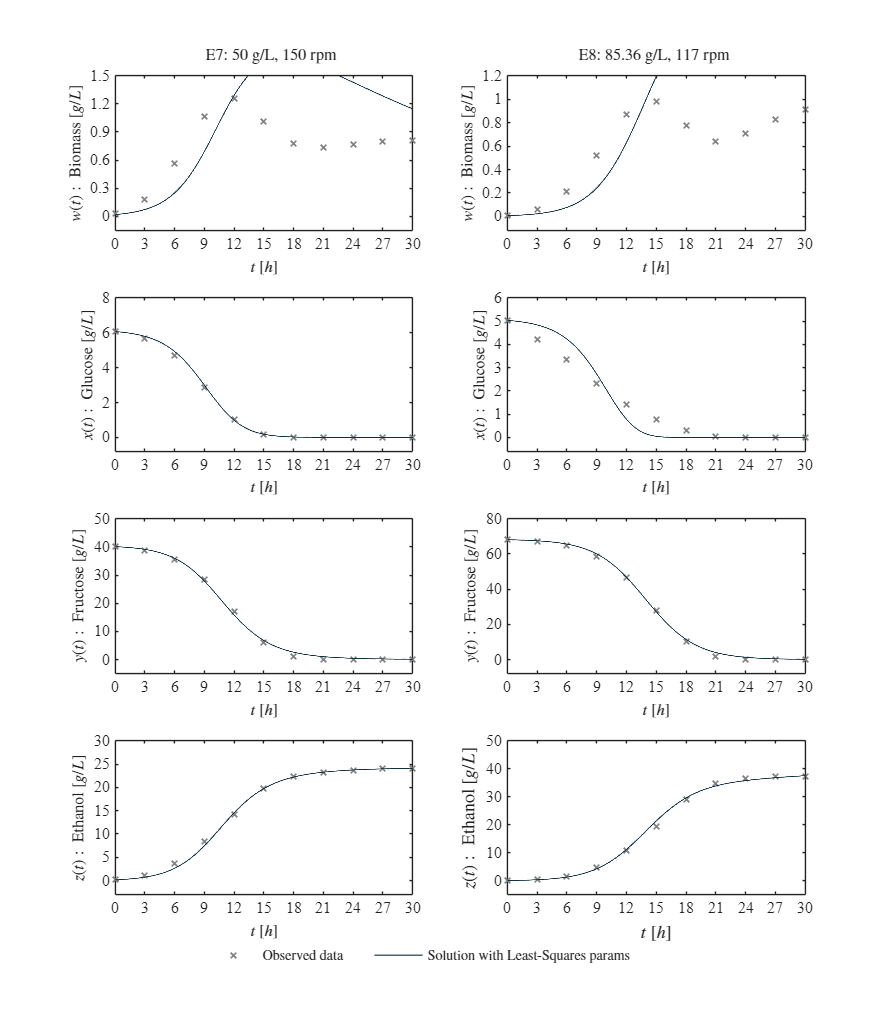

plot4x2([E7_t;E7],E7_model,[E8_t;E8],E8_model);....
subplot(4,2,1); ylim([-1.5/10 1.5]); yticks(0:0.3:1.5);...
subplot(4,2,3); ylim([-8/10 8]); yticks(0:2:8);...
subplot(4,2,5); ylim([-50/10 50]); yticks(0:10:50);...
subplot(4,2,7); ylim([-30/10 30]); yticks(0:5:30);...
subplot(4,2,2); ylim([-1.2/10 1.2]); yticks(0:0.2:1.2);...
subplot(4,2,4); ylim([-6/10 6]); yticks(0:1:6);...
subplot(4,2,6); ylim([-80/10 80]); yticks(0:20:80);...
subplot(4,2,8); ylim([-50/10 50]); yticks(0:10:50);... 
dim = [0.22 0.86 0.1 0.1];...
str = {'E7: 50 g/L, 150 rpm'};...
A7 = annotation('textbox', dim, 'String', str, 'FitBoxToText', 'on','EdgeColor', 'none','FontSize',10);
set(A7,'Interpreter','Latex');...
dim = [0.64 0.86 0.1 0.1];...
str = {'E8: 85.36 g/L, 117 rpm'};...
A8 = annotation('textbox', dim, 'String', str, 'FitBoxToText', 'on','EdgeColor', 'none','FontSize',10);
set(A8,'Interpreter','Latex');...
exportgraphics(gcf,'ITD00185_E7E8.pdf','ContentType','vector')

### E9: 85.36 g/L - 142 rpm and E10: 100 g/L - 125 rpm

E9_raw = readmatrix("data.xlsx","Sheet","E9");
E9_w = smoothdata(E9_raw(:,2), 'gaussian', 5);
E9_x = smoothdata(E9_raw(:,3), 'gaussian', 5); 
E9_y = smoothdata(E9_raw(:,4), 'gaussian', 5);
E9_z = smoothdata(E9_raw(:,5), 'gaussian', 5);
E9_t = E9_raw(:,1); E9 = [E9_w;E9_x;E9_y;E9_z];
rhoE9 = Experiment(E9_t,E9,rho0);...
E9_model = model([E9_x(1);E9_y(1);E9_z(1)],rhoE9,max(E9_t));

Degrees of freedom: 36
t-student value: 2.0281
Significance value (alpha): 0.05
 
    Parameters    Estimate        SE           MoE         ci_low       ci_high      Pvalue 
    __________    _________    _________    _________    __________    _________    ________

     {["p1"]}     0.0050017    0.0005851    0.0011866     0.0038151    0.0061883    3.44e-10
     {["p2"]}        0.0001      0.12602      0.25558      -0.25548      0.25568     0.99937
     {["p3"]}         1e-05    0.0029737     0.006031     -0.006021     0.006041     0.99734
     {["p4"]}             1      0.52645       1.0677     -0.067685       2.0677     0.06553
     {["p6"]}       0.17099     0.066275      0.13441      0.036578       0.3054    0.014107
     {["p8"]}      0.084334 

E10_raw = readmatrix("data.xlsx","Sheet","E10");
E10_w = smoothdata(E10_raw(:,2), 'gaussian', 5);
E10_x = smoothdata(E10_raw(:,3), 'gaussian', 5);
E10_y = smoothdata(E10_raw(:,4), 'gaussian', 5);
E10_z = smoothdata(E10_raw(:,5), 'gaussian', 5);
E10_t = E10_raw(:,1); E10 = [E10_w;E10_x;E10_y;E10_z];
rhoE10 = Experiment(E10_t,E10,rho0);...
E10_model = model([E10_x(1);E10_y(1);E10_z(1)],rhoE10,max(E10_t));

Degrees of freedom: 36
t-student value: 2.0281
Significance value (alpha): 0.05
 
    Parameters     Estimate         SE           MoE          ci_low       ci_high       Pvalue  
    __________    __________    __________    __________    __________    _________    __________

     {["p1"]}      0.0051873    0.00038687    0.00078461     0.0044027    0.0059719    1.4428e-15
     {["p2"]}      0.0037887      0.069561       0.14108      -0.13729      0.14486       0.95687
     {["p3"]}     0.00074897     0.0014733     0.0029881    -0.0022391     0.003737       0.61431
     {["p4"]}        0.30852       0.12384       0.25115      0.057365      0.55966      0.017472
     {["p6"]}        0.17018      0.046565      0.094437      0.075741      0.26462    0.00

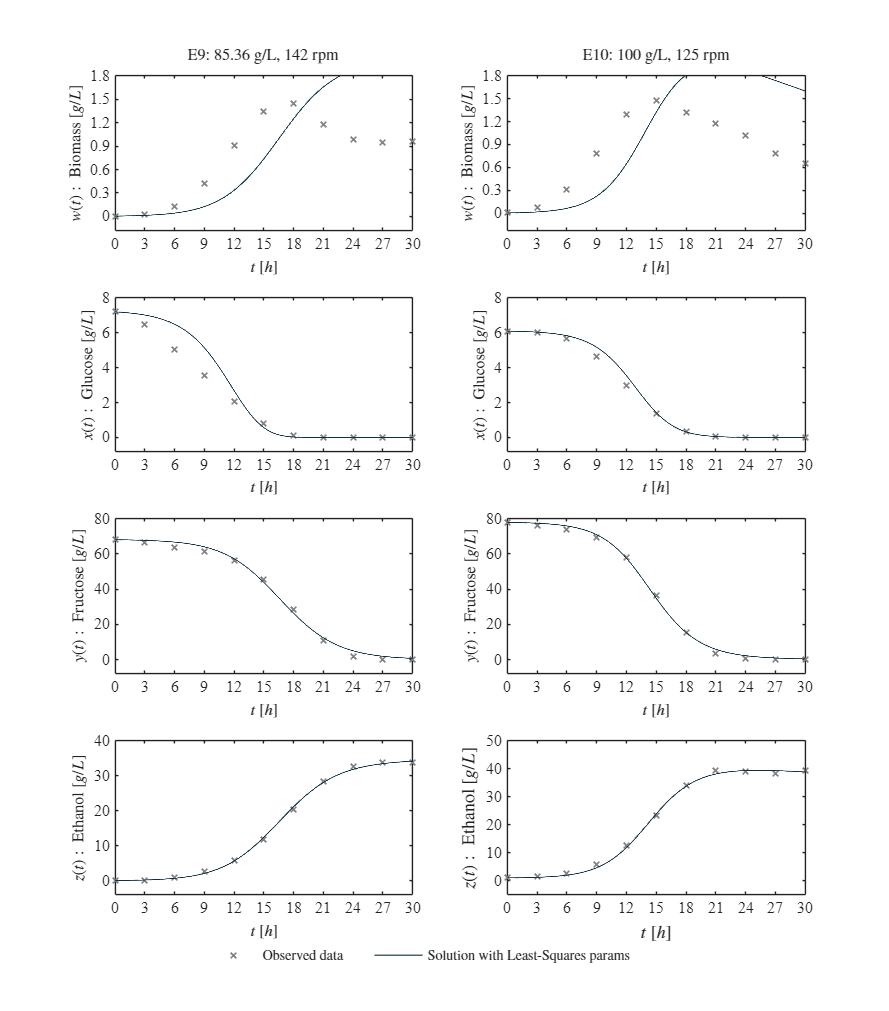

plot4x2([E9_t;E9],E9_model,[E10_t;E10],E10_model);....
subplot(4,2,1); ylim([-1.8/10 1.8]); yticks(0:0.3:1.8);...
subplot(4,2,3); ylim([-8/10 8]); yticks(0:2:8);...
subplot(4,2,5); ylim([-80/10 80]); yticks(0:20:80);...
subplot(4,2,7); ylim([-40/10 40]); yticks(0:10:40);...
subplot(4,2,2); ylim([-1.8/8 1.8]); yticks(0:0.3:1.8);...
subplot(4,2,4); ylim([-8/10 8]); yticks(0:2:8);...
subplot(4,2,6); ylim([-80/10 80]); yticks(0:20:80);...
subplot(4,2,8); ylim([-50/10 50]); yticks(0:10:50);...
dim = [0.2 0.86 0.1 0.1];...
str = {'E9: 85.36 g/L, 142 rpm'};...
A9 = annotation('textbox', dim, 'String', str, 'FitBoxToText', 'on','EdgeColor', 'none','FontSize',10);
set(A9,'Interpreter','Latex');...
dim = [0.645 0.86 0.1 0.1];...
str = {'E10: 100 g/L, 125 rpm'};...
A10 = annotation('textbox', dim, 'String', str, 'FitBoxToText', 'on','EdgeColor', 'none','FontSize',10);
set(A10,'Interpreter','Latex');...
exportgraphics(gcf,'ITD00185_E9E10.pdf','ContentType','vector')

## Functions

function sys = model(IC,rho,tend)
    dt = 1e-2;
    p1 = rho(1); p2 = rho(2); p3 = rho(3); p4 = rho(4);
    p6 = rho(5); p8 = rho(6); p9 = rho(7); w0 = rho(8);
    p5 = log(2)/840960;
    p7 = log(2)/1680;
    p0 = 1;
    n = round(tend/dt);
    t = (0:dt:tend)';
    w = zeros(length(t),1); w(1) = w0;
    W = zeros(length(t),1); W(1) = 0;
    x = zeros(length(t),1); x(1) = IC(1);
    y = zeros(length(t),1); y(1) = IC(2);
    z = zeros(length(t),1); z(1) = IC(3);

    for i = 1:n
        [fw,fW,fx,fy,fz] = f(w(i),W(i),x(i),y(i),z(i));
        wn = w(i) + fw*dt;
        Wn = W(i) + fW*dt;
        xn = x(i) + fx*dt;
        yn = y(i) + fy*dt;
        zn = z(i) + fz*dt;
        [fwn,fWn,fxn,fyn,fzn] = f(wn,Wn,xn,yn,zn);
        w(i+1) = w(i) + (fw + fwn)*dt/2;
        W(i+1) = W(i) + (fW + fWn)*dt/2;
        x(i+1) = x(i) + (fx + fxn)*dt/2;
        y(i+1) = y(i) + (fy + fyn)*dt/2;
        z(i+1) = z(i) + (fz + fzn)*dt/2;
    end

    function [dw,dW,dx,dy,dz] = f(w,W,x,y,z)
        exp_term = exp(max(min(-p2 * W, 50.0), -50.0));
        dw = +p1 * w * (x + y) * exp_term - p3 * w * (p0 + z);
        dW = +w;
        dx = -p4 * x * w - p5 * x;
        dy = -p6 * y * w - p7 * y;
        dz = +p8 * (p0 + x + y) * w - p9 * z;
    end

    sys = [t,w,x,y,z];
end

function Estimate = Experiment(t,fo,rho0)
    to = [t;t;t;t];
    ic = reshape(fo,[],4);
    p5 = log(2)/840960;
    p7 = log(2)/1680;
    p0 = 1;

    function fa = model(rho,ta)
        dt = 1e-2;
        p1 = rho(1); p2 = rho(2); p3 = rho(3); p4 = rho(4);
        p6 = rho(5); p8 = rho(6); p9 = rho(7); w0 = rho(8);
        time = (0:dt:max(ta))';
        n = round(max(ta)/dt);
        w = zeros(length(t),1); w(1) = w0;
        W = zeros(length(t),1); W(1) = 0;
        x = zeros(length(t),1); x(1) = ic(1,2);
        y = zeros(length(t),1); y(1) = ic(1,3);
        z = zeros(length(t),1); z(1) = ic(1,4);
            
        for i = 1:n
            [fw,fW,fx,fy,fz] = f(w(i),W(i),x(i),y(i),z(i));
            wn = w(i) + fw*dt;
            Wn = W(i) + fW*dt;
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            zn = z(i) + fz*dt;
            [fwn,fWn,fxn,fyn,fzn] = f(wn,Wn,xn,yn,zn);
            w(i+1) = w(i) + (fw + fwn)*dt/2;
            W(i+1) = W(i) + (fW + fWn)*dt/2;
            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
            z(i+1) = z(i) + (fz + fzn)*dt/2;
        end

        function [dw,dW,dx,dy,dz] = f(w,W,x,y,z)
            exp_term = exp(max(min(-p2 * W, 50.0), -50.0));
            dw = +p1 * w * (x + y) * exp_term - p3 * w * (p0 + z);
            dW = +w;
            dx = -p4 * x * w - p5 * x;
            dy = -p6 * y * w - p7 * y;
            dz = +p8 * (p0 + x + y) * w - p9 * z;
        end
        wi = interp1(time, w, t, 'linear');
        xi = interp1(time, x, t, 'linear');
        yi = interp1(time, y, t, 'linear');
        zi = interp1(time, z, t, 'linear');
        
        fa = [wi;xi;yi;zi];
    end
    
    par = numel(rho0);
    bounds = [ ...
        1e-4,  1;   ... % p1
        1e-4,  1e-1;... % p2
        1e-5,  1e-1;... % p3
        1e-3,  1;   ... % p4
        1e-3,  1;   ... % p6
        1e-4,  1e-1;   ... % p8
        1e-6,  1e-2;   ... % p9
        0.0,    10];  % w0

    opts = optimoptions('lsqcurvefit','MaxFunctionEvaluations',1000,'MaxIterations',1000,...
        'FunctionTolerance',1E-12,'StepTolerance',1E-12,'OptimalityTolerance',1E-12,'Display','off');
    [Estimate,~,residual,~,~,~,jacobian]  = lsqcurvefit(@model,rho0,to,fo,bounds(:,1),bounds(:,2),opts);
    
    n_obs = numel(fo);
    dof = n_obs - par;
    covm = full(inv(jacobian'*jacobian))*((residual'*residual)/dof);
    SE = sqrt(max(diag(covm), 0.0));
    alpha = 0.05;
    tcrit = tinv(1 - alpha/2, dof);
    MoE = tcrit * SE;
    ci_low = Estimate(:) - MoE;
    ci_high = Estimate(:) + MoE;
    CI95 = [ci_low,ci_high];
    tvals = abs(Estimate(:) ./ SE);
    pvals = 2 * tcdf(-tvals, dof);
    Pvalue = max(pvals, realmin('double'));
    
    ss_tot = sum((fo - mean(fo)).^2);
    rss = sum((residual).^2);
    R2 = 1 - rss / max(ss_tot, 1e-16);
    R2_adj =  1.0 - (1.0 - R2) * (n_obs - 1.0) / (n_obs - par - 1);

    aic = n_obs * log(max(rss, 1e-16) / n_obs) + 2 * par;
    if par > 0 && (n_obs / par) < 40 && ((n_obs - par - 1) > 0)
        aic = aic + (2 * par * (par + 1)) / (n_obs - par - 1);
    end

    Parameters = {"p1","p2","p3","p4","p6","p8","p9","w0"}';
    Results = table(Parameters,Estimate,SE,MoE,ci_low,ci_high,Pvalue);
    disp(['Degrees of freedom: ',num2str(dof)])
    disp(['t-student value: ',num2str(tcrit)])
    disp(['Significance value (alpha): ',num2str(alpha)])
    disp(' '); disp(Results)
    fprintf(['\nR-cuadrada ajustada: ', num2str(R2_adj)]);...
    fprintf(['\nSuma residual de cuadrados: ', num2str(rss)]);...
    fprintf(['\nCritetio de información de Akaike: ', num2str(aic)]);...
end

### Plot solutions: Data vs Model simulation

function plot4x2(fdata1,fode1,fdata2,fode2)
    fdata1 = reshape(fdata1,[],5);
    fdata2 = reshape(fdata2,[],5);
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,22,25])
    fs = 10;
    clr1 = [0.5,0.5,0.5];
    clr7 = [15,48,64]/255;

    subplot(4,2,1); hold on; box on; grid off; fontsize(fs,"points"); set(gca,'FontName','Times New Roman')
    xline(30,'--');
    plot(fdata1(:,1),fdata1(:,2),'x','MarkerSize',5,'LineWidth',1,'Color',clr1)
    plot(fode1(:,1),fode1(:,2),'-','LineWidth',0.75,'Color',clr7)
    xlim([0 30]); xticks(0:3:30);
    % xlim([0 60]); xticks(0:10:60);
    xlabel('$t$ $[h]$','Interpreter','latex')
    ylabel('$w(t):$ Biomass $[g/L]$','Interpreter','latex')
    subplot(4,2,3); hold on; box on; grid off; fontsize(fs,"points"); set(gca,'FontName','Times New Roman')
    xline(30,'--');
    plot(fdata1(:,1),fdata1(:,3),'x','MarkerSize',5,'LineWidth',1,'Color',clr1)
    plot(fode1(:,1),fode1(:,3),'-','LineWidth',0.75,'Color',clr7)
    xlim([0 30]); xticks(0:3:30);
    % xlim([0 60]); xticks(0:10:60);
    xlabel('$t$ $[h]$','Interpreter','latex')
    ylabel('$x(t):$ Glucose $[g/L]$','Interpreter','latex')
    subplot(4,2,5); hold on; box on; grid off; fontsize(fs,"points"); set(gca,'FontName','Times New Roman')
    xline(30,'--');
    plot(fdata1(:,1),fdata1(:,4),'x','MarkerSize',5,'LineWidth',1,'Color',clr1)
    plot(fode1(:,1),fode1(:,4),'-','LineWidth',0.75,'Color',clr7)
    xline(30,'--');
    xlim([0 30]); xticks(0:3:30);
    % xlim([0 60]); xticks(0:10:60);
    xlabel('$t$ $[h]$','Interpreter','latex')
    ylabel('$y(t):$ Fructose $[g/L]$','Interpreter','latex')
    subplot(4,2,7); hold on; box on; grid off; fontsize(fs,"points"); set(gca,'FontName','Times New Roman')
    xline(30,'--');
    plot(fdata1(:,1),fdata1(:,5),'x','MarkerSize',5,'LineWidth',1,'Color',clr1)
    plot(fode1(:,1),fode1(:,5),'-','LineWidth',0.75,'Color',clr7)
    xlim([0 30]); xticks(0:3:30);
    % xlim([0 60]); xticks(0:10:60);
    xlabel('$t$ $[h]$','Interpreter','latex')
    ylabel('$z(t):$ Ethanol $[g/L]$','Interpreter','latex')

    subplot(4,2,2); hold on; box on; grid off; fontsize(fs,"points"); set(gca,'FontName','Times New Roman')
    xline(30,'--');
    plot(fdata2(:,1),fdata2(:,2),'x','MarkerSize',5,'LineWidth',1,'Color',clr1)
    plot(fode2(:,1),fode2(:,2),'-','LineWidth',0.75,'Color',clr7)
    xlim([0 30]); xticks(0:3:30);
    % xlim([0 60]); xticks(0:10:60);
    xlabel('$t$ $[h]$','Interpreter','latex')
    ylabel('$w(t):$ Biomass $[g/L]$','Interpreter','latex')
    subplot(4,2,4); hold on; box on; grid off; fontsize(fs,"points"); set(gca,'FontName','Times New Roman')
    xline(30,'--');
    plot(fdata2(:,1),fdata2(:,3),'x','MarkerSize',5,'LineWidth',1,'Color',clr1)
    plot(fode2(:,1),fode2(:,3),'-','LineWidth',0.75,'Color',clr7)
    xlim([0 30]); xticks(0:3:30);
    % xlim([0 60]); xticks(0:10:60);
    xlabel('$t$ $[h]$','Interpreter','latex')
    ylabel('$x(t):$ Glucose $[g/L]$','Interpreter','latex')
    subplot(4,2,6); hold on; box on; grid off; fontsize(fs,"points"); set(gca,'FontName','Times New Roman')
    xline(30,'--');
    plot(fdata2(:,1),fdata2(:,4),'x','MarkerSize',5,'LineWidth',1,'Color',clr1)
    plot(fode2(:,1),fode2(:,4),'-','LineWidth',0.75,'Color',clr7)
    xlim([0 30]); xticks(0:3:30);
    % xlim([0 60]); xticks(0:10:60);
    xlabel('$t$ $[h]$','Interpreter','latex')
    ylabel('$y(t):$ Fructose $[g/L]$','Interpreter','latex')
    subplot(4,2,8); hold on; box on; grid off; fontsize(fs,"points"); set(gca,'FontName','Times New Roman')
    xline(30,'--','HandleVisibility', 'off');
    plot(fdata2(:,1),fdata2(:,5),'x','MarkerSize',5,'LineWidth',1,'Color',clr1)
    plot(fode2(:,1),fode2(:,5),'-','LineWidth',0.75,'Color',clr7)
    xlim([0 30]); xticks(0:3:30);
    % xlim([0 60]); xticks(0:10:60);
    xlabel('$t$ $[h]$','Interpreter','latex')
    ylabel('$z(t):$ Ethanol $[g/L]$','Interpreter','latex')

    L = legend('Observed data $\quad$','Solution with Least-Squares params');
    set(L,'Interpreter','Latex','Box','Off','Orientation','Horizontal','NumColumns',2,'Position', [0.25 0.03 0.47, 0.05])
end